# Representacion de señales.

- Tomamos un intervalo.

- Tomamos una serie de puntos. 

x = linspace(0,1,1024)

x =          0    0.0010    0.0020    0.0029    0.0039    0.0049    0.0059    0.0068    0.0078    0.0088    0.0098    0.0108    0.0117    0.0127    0.0137    0.0147    0.0156    0.0166    0.0176    0.0186    0.0196    0.0205    0.0215    0.0225    0.0235    0.0244    0.0254    0.0264    0.0274    0.0283    0.0293    0.0303    0.0313    0.0323    0.0332    0.0342    0.0352    0.0362    0.0371    0.0381    0.0391    0.0401    0.0411    0.0420    0.0430    0.0440    0.0450    0.0459    0.0469    0.0479


% 1/1024, 2/1024

          3. Evaluamos la señal    $g(x)=20x^2(1-x)^4\cos(12\pi x)$

signal = (20*x.^2).*((1-x).^4).*cos(12*pi*x)

signal =          0    0.0000    0.0001    0.0002    0.0003    0.0005    0.0007    0.0009    0.0011    0.0014    0.0017    0.0020    0.0024    0.0027    0.0031    0.0034    0.0038    0.0042    0.0045    0.0049    0.0052    0.0055    0.0058    0.0061    0.0063    0.0065    0.0067    0.0068    0.0069    0.0069    0.0069    0.0067    0.0066    0.0063    0.0060    0.0056    0.0052    0.0046    0.0040    0.0033    0.0025    0.0016    0.0007   -0.0004   -0.0016   -0.0028   -0.0042   -0.0056   -0.0071   -0.0088


Representacion grafica

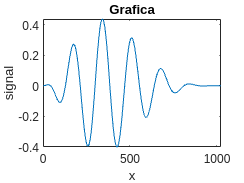

plot(signal)
title('Grafica')
xlabel('x')
ylabel('signal')
axis([0 length(signal) min(signal) max(signal)])

# Wavelets 1-D desde la linea de comandos

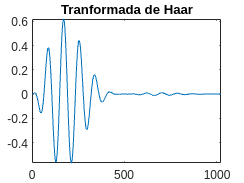

% Calculamos la tranformada de Haar de la señal 
% Nivel 1
s = signal;
w = 'haar';
Wavelet_utilizada = w;
[C,L] = wavedec(s,1,w); 
% C -> Transformada wavelet. Vector del mismo tamaño que la original
% L -> Las dimensiones de cada trozo. Cuando yo calculo la transformada a
      % un cierto nivel 
% s -> la señal a descomponer
% 1 -> Nivel de descomposicion
% w -> la wavelet a utilizar
figure; plot(C); title('Tranformada de Haar');
axis([0 length(C) min(C) max(C)]);

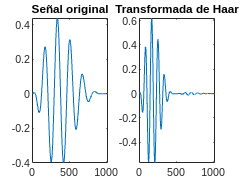


% La original y la transformada jutas
figure; subplot(1,2,1)
plot(s); title('Señal original');
axis([0 length(s) min(s) max(s)]);
subplot(1,2,2)
plot(C);title('Transformada de Haar')
axis([0 length(C) min(C) max(C)]);

Vemos que A1 es las frecuencias bajas que van de 0 a 400 y D1 es de 400 para arriba.

Ahora si quiero extraer de la transformada cada parte por separado de aproximacion y de detalle utilizo los comandos de appcoef y detcoef, se extrae las subseñales por separado.

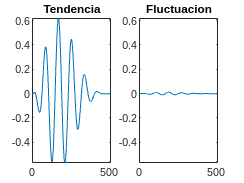

% Coeficientes de tendencia y fluctuacion para forma las subseñales
cA1 = appcoef(C,L,w,1);
cD1 = detcoef(C,L,1);

figure;subplot(1,2,1)
plot(cA1);title('Tendencia');
axis([0 length(cA1) min(cA1) max(cA1)]);
subplot(1,2,2)
plot(cD1); title('Fluctuacion')
axis([0 length(cD1) min(cA1) max(cA1)])